clear;
close all;
addpath('../include');

isFigure = true; % whether show figure
isSave = true; % whether save related files for evaluation
data_set = 'INDOOR';
sequence = 'all_rooms';
frame_num = 0;
frame_num = frame_num+1;

INDOOR_reading_dir = '../example_data/INDOOR_dataset';
INDOOR_saving_dir = '../example_data/INDOOR_results';

% lidarConfig
full_num_lasers = 64; % total channel of the input point cloud
num_lasers = 64; % number of channels that will be processed
img_length = 1024; % length of the depth image when point cloud transferring into a depth image
length_percentage = []; % the percentage of points that will preserve depends on the max distance of the point cloud
max_length = []; % points will be removed larger than this value, which depends on 'length_percentage'
min_length = []; % points will be removed lower than this value
row_times = 2; % row times that upsampling will achieve
col_times = 2; % column times that upsampling will achieve
fov_up = []; % lidar vertical FoV configuration
fov_down = []; % lidar vertical FoV configuration
lidarConfig = lidar_config_function('data_set',data_set,'num_lasers',num_lasers,'full_num_lasers',full_num_lasers,'img_length',img_length,'row_times',row_times,'col_times',col_times);

% thresholdConfig
avg_filter_thres = 0.5;
rmv_filter_thres = 0.5;
avg_error_thres_patch = 0.1; % another threshold to break the iteration loop; if 'is_1_1_recons_only=true', this recommand value is 0.01
remove = 0.5; % remove the points which larger than this error after breaking the iteration loop
u = []; % the threshold to define a horizontal cliff
v = []; % the threshold to define a vertical cliff
thresholdConfig = threshold_config_function('data_set',data_set,'avg_filter_thres',avg_filter_thres,'rmv_filter_thres',rmv_filter_thres,'avg_error_thres_patch',avg_error_thres_patch,'remove',remove);

% patchConfig
degree_initial = 1;
degree_iter_step = 1;
degree_max = 100;
Pr = 4;  % lower Pr with faster extraction speed, more accurate result, high compression percentage. (When avg_error_thres_patch is large enough）
patch_row_rso = Pr/(lidarConfig.full_num_lasers/lidarConfig.num_lasers)*lidarConfig.row_times; % row patch size
patch_col_rso = Pr*lidarConfig.col_times; % col patch size
row_overlap_step = 2; % row overlap between neighbor patches
col_overlap_step = 2; % col overlap between neighbor patches
k = 9; % adjust the weight between training cell and testing cell
is_1_1_recons_only = false; % whether focus on 1:1 reconstruction task
if (is_1_1_recons_only)
    lidarConfig.row_times = 1;
    lidarConfig.col_times = 1;
    thresholdConfig.avg_error_thres_patch = 0.01;    
    patch_row_rso = Pr/(lidarConfig.full_num_lasers/lidarConfig.num_lasers)*lidarConfig.row_times; % row patch size
    patch_col_rso = Pr*lidarConfig.col_times; % col patch size
    row_overlap_step = 0;
    col_overlap_step = 0;
end
patchConfig = patch_config_function('degree_initial',degree_initial,'degree_iter_step',degree_iter_step,'degree_max',degree_max,'patch_row_rso',patch_row_rso,'patch_col_rso',patch_col_rso,'row_overlap_step',row_overlap_step,'col_overlap_step',col_overlap_step,'k',k,'is_1_1_recons_only',is_1_1_recons_only);

% reconsConfig
recons_row_times = 8; % R_row, times that would be increased of row points after reconstruction compared with the original point cloud
recons_col_times = 2; % R_col, times that would be increased of column points after reconstruction
reconsConfig = recons_config_function('recons_row_times',recons_row_times,'recons_col_times',recons_col_times,'lidarConfig',lidarConfig);

ply_dir = [INDOOR_reading_dir '/' sequence];
ply_files = dir(ply_dir);
ply_files(1:2,:) = [];
% read pcd files
ply_file = [ply_dir '/' ply_files(frame_num).name];
[inputPointCloud,lidarConfig] = point_cloud_initial_function(data_set,lidarConfig,ply_file);
[save_sampling_dir,sampling_remove_dir,save_coefficients_dir,save_recons_dir,save_evaluation_error_dis_file,save_evaluation_compression_file] = create_dir_function(INDOOR_saving_dir,sequence,frame_num,lidarConfig,thresholdConfig,patchConfig,reconsConfig);

C++ Sampling time: 0.233s
Matlab Calculation time 0.052608s
Actual Extraction Time: 0.047(s)


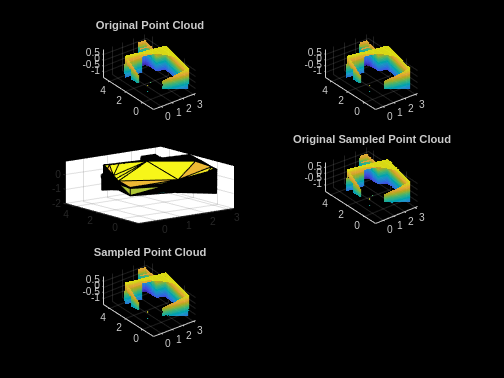

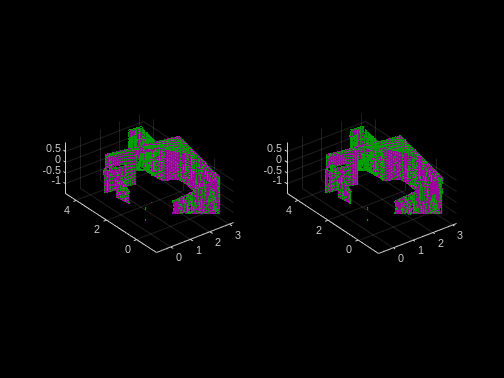

[lidarConfig,coefficient_r_cell,mask_update,~,square_grid,points_up] = SPHARM_INDOOR_extraction_mex(frame_num,inputPointCloud,lidarConfig,thresholdConfig,patchConfig,save_sampling_dir,sampling_remove_dir,save_coefficients_dir,isSave,isFigure);

Reconstruction Time: 0.08(s)


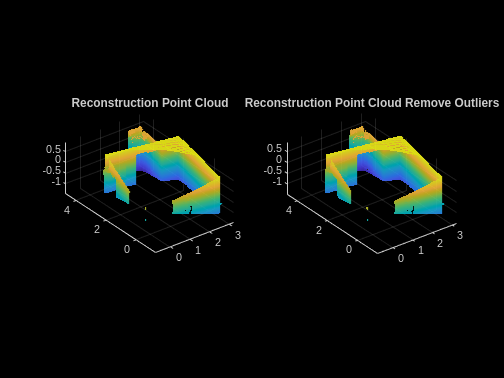

[reconsPointCloud,reconsPointCloudFiltered] = SPHARM_reconstruction_mex(lidarConfig,coefficient_r_cell,mask_update,reconsConfig,save_recons_dir,isSave,isFigure);

% will compare with the ground truth point cloud
% continuous reconstruction.
pt_point_cloud_original = pcread(ply_file);
point_cloud_original = pt_point_cloud_original.Location;
point_cloud_original = point_cloud_original-mean(point_cloud_original);
[~,~] = SPHARM_evaluation(data_set,lidarConfig,save_coefficients_dir,mask_update,point_cloud_original,reconsPointCloud,frame_num,save_evaluation_error_dis_file,save_evaluation_compression_file,isSave,save_sampling_dir);

Frame: 0 Mean Distance Error: 0.0048184(m) Std: 0.0064943
Frame: 0 Mat File Compression Percentage: 14.1535%
Frame: 0 Double Compression Percentage: 12.8858%
